# Computer Vision

# **Lab 2. **Basic Image Processing Techniques

**Student(s):**

**Date:**

The main objective of this practice is to become familiar with the basic image processing techniques using Matlab's ***Image Processing Toolbox***. For this, exercises are proposed on geometric operations, histogram equalization, design and implementation of filters, noise elimination, image filtering in the space and frequency domain. Most enhancement techniques are applied to intensity (grayscale) images. To improve an RGB image, we will normally work with the matrices of the red, green and blue components separately. To carry out the exercises, it is initially proposed to use the images available in the virtual classroom of the subject, but others can be used as long as the format and luminosity characteristics required by the exercise are maintained (for example, if they must be in color, indexed, dark, with low contrast, etc...). In any case, it is very important to verify the format of each image before processing it: know if it is RGB, indexed, if the values are integers (uint8, etc.), or if they are float/double, since frequently the functions only work with a specific data type. This is especially important when the exercises do not indicate which conversion should be performed or when photos other than those initially indicated in the statement are used. If our image does not have the appropriate format, the functions may give an error (indicating the expected type of data) or provide an unexpected result. In either case we must verify the type of data expected by the function and change the image format with the appropriate conversion function.

**The practice report will be completed in this same .mlx file**, adding the name of the author/authors of the group, date, and inserting the code and pertinent comments in each section. The different parts will be independent sections (you must insert "section break" between them), and the results will be displayed together with subplot when appropriate. 

The **delivery** will be made in the Virtual Classroom of the subject: Contents -> Labs -> Lab 2. Report.

clear all
close all

Implement the following code, display the results obtained and justify them:

1. Open and view at least 2 color images, one RGB type and one indexed. To find out the format of each one you can previously use *imageinfo* (RGB, indexed color map, etc.). When opening them you must use the appropriate variables (J, X, map, etc...) so that they are displayed correctly. Use different figures for each one (avoiding, in this case, the subplot command). 

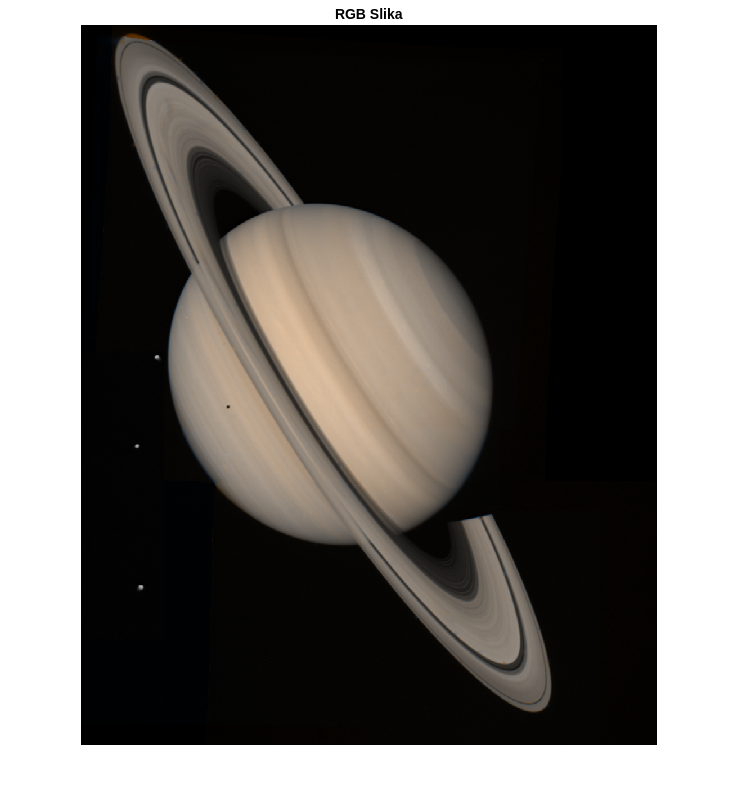

%OVO NE ZNAM JE LI DOBRO
% Otvorite i prikažite RGB sliku
RGB_image = imread('saturn.png');
figure;
imshow(RGB_image);
title('RGB Slika');

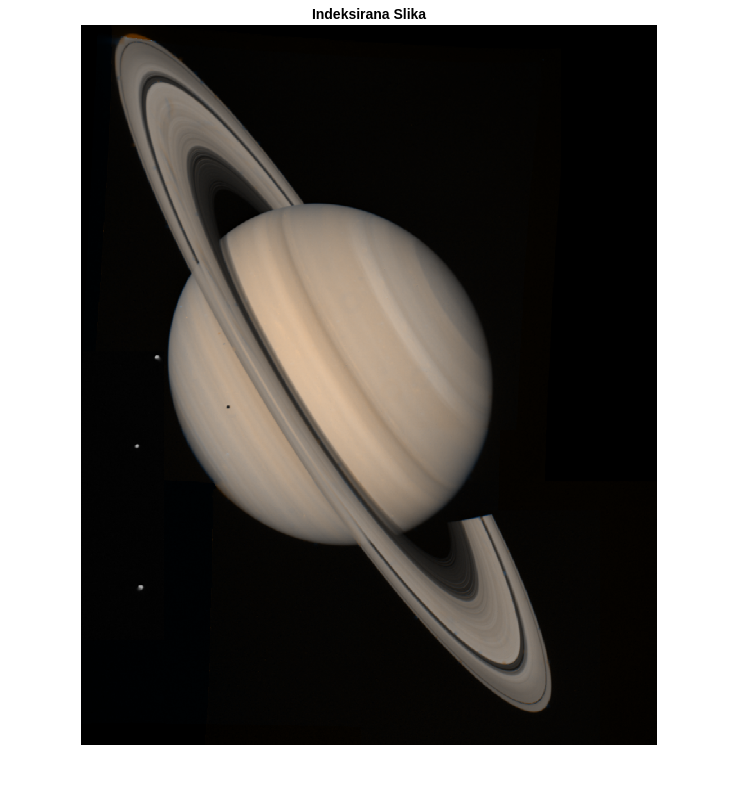


% Otvorite i prikažite indeksiranu sliku
indexed_image = imread('saturn.png'); 
figure;
imshow(indexed_image);
title('Indeksirana Slika');

2. Convert the indexed image to grayscale (Igray image) and do the following with it:

    2.1 Modify the brightness and contrast. View the images (original and output) and their histograms together using the *subplot* command. Explain when the modification is in brightness and when it is in contrast, justifying the values of the intervals used in each case..

    2.2 Binarize the Igris image with the *im2bw* function and display the result.

    2.3 Obtain the negative of the Igris image.

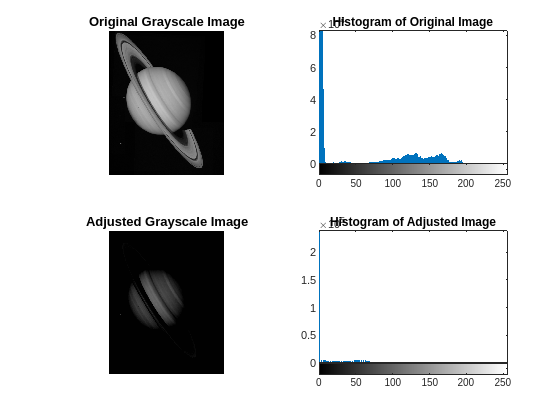

% Convert indexed image to grayscale
Igray = rgb2gray(indexed_image);

% Define brightness and contrast adjustment values
brightness = 0.5; % Adjust this value as needed
contrast = 1.5;   % Adjust this value as needed

% Apply brightness and contrast adjustments
adjusted_image = brightness + contrast * (Igray - 128);
adjusted_image = uint8(adjusted_image);

% Display the original and adjusted images and their histograms
figure;
subplot(2, 2, 1);
imshow(Igray);
title('Original Grayscale Image');
subplot(2, 2, 2);
imhist(Igray);
title('Histogram of Original Image');

subplot(2, 2, 3);
imshow(adjusted_image);
title('Adjusted Grayscale Image');
subplot(2, 2, 4);
imhist(adjusted_image);
title('Histogram of Adjusted Image');

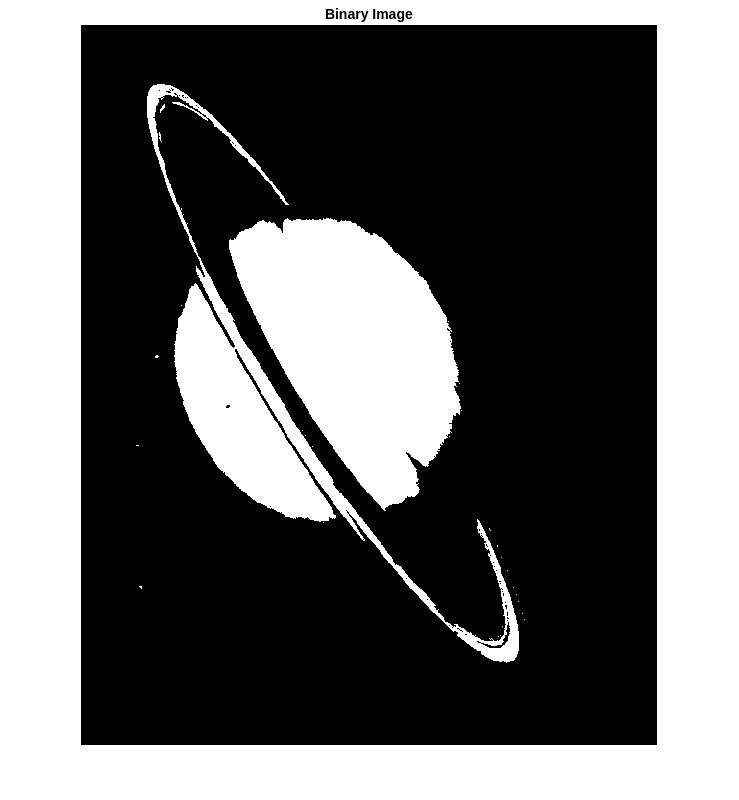



% Binarize the Igray image
threshold = 0.5; % Adjust this threshold as needed
binary_image = im2bw(Igray, threshold);

% Display the binary image
figure;
imshow(binary_image);
title('Binary Image');

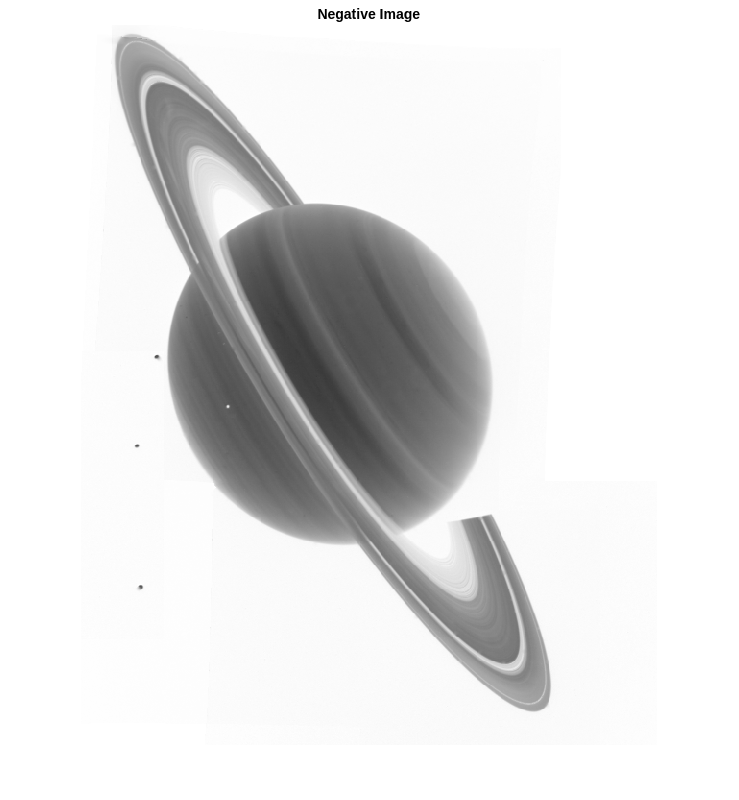



% Get the negative of the Igray image
negative_image = 255 - Igray;

% Display the negative image
figure;
imshow(negative_image);
title('Negative Image');

3. Do the following with image "avion1.jpg":

    3.1 Apply the logarithm, previously calculating the optimal value of K, to ensure that the maximum gray level at the output is the maximum possible. View the original and output images and their histograms and observe the improvement obtained. Try using different K values than the one calculated and comment on the results.

    3.2 Perform a gamma correction. Try different gamma values and analyze the effect of each on the output image.

    3.3 Equalize its histogram with 256, 64 and 8 bins (see histeq help). View the images (original and output) and their histograms and comment on the differences.

%nekaj tu ne valja jos
% Load the image
plane_image = imread('avion1.jpg');

Error using imread>get_full_filename
File "avion1.jpg" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);


% Calculate the optimal value of K
K = 255 / log(1 + max(plane_image(:)));

% Apply the logarithmic transformation
log_transformed_image = uint8(K * log(double(plane_image) + 1));

% Display the original and transformed images and their histograms
figure;
subplot(2, 2, 1);
imshow(plane_image);
title('Original Image');
subplot(2, 2, 2);
imhist(plane_image);
title('Histogram of Original Image');

subplot(2, 2, 3);
imshow(log_transformed_image);
title('Logarithmic Transformed Image');
subplot(2, 2, 4);
imhist(log_transformed_image);
title('Histogram of Transformed Image');


% Apply gamma correction with different gamma values
gamma_values = [0.5, 1.0, 1.5, 2.0]; % Experiment with different gamma values

figure;
for i = 1:length(gamma_values)
    gamma_corrected_image = imadjust(plane_image, [], [], gamma_values(i));
    subplot(2, 2, i);
    imshow(gamma_corrected_image);
    title(['Gamma = ', num2str(gamma_values(i))]);
end


% Equalize histogram with different number of bins
nBins_values = [256, 64, 8]; % Experiment with different number of bins

figure;
for i = 1:length(nBins_values)
    equalized_image = histeq(plane_image, nBins_values(i));
    subplot(2, 2, i);
    imshow(equalized_image);
    title(['Bins = ', num2str(nBins_values(i))]);
end



4. Now work with image "matricula.jpg":

    4.1 Find out its dimensions (rows x columns). Resize it to be half the width and half the height. Display both images. To see the size change you must use the *truesize* option after *imshow* so that the images do not adjust their size to that of the window.

    4.2 Rotate it through an angle of 65.3º (for example), using the *nearest* and *bicubic* interpolation methods (parameters of the *imrotate* function). Magnify the images enough to see the differences between both results and explain them.

Nekaj tu ne valja jos
% Load "matricula.jpg"
matricula = imread("matricula.jpg");

% 4.1 Find dimensions and resize
[rows, cols, ~] = size(matricula);
half_width = cols / 2;
half_height = rows / 2;
resized_image = imresize(matricula, [half_height, half_width]);

% 4.2 Rotate the image with different interpolation methods
angle = 65.3;
rotated_nearest = imrotate(matricula, angle, 'nearest', 'crop');
rotated_bicubic = imrotate(matricula, angle, 'bicubic', 'crop');

% Display all four images using subplot
figure;

% Original Image
subplot(2, 2, 1);
imshow(matricula);
title('Original Image');

% Resized Image
subplot(2, 2, 2);
imshow(resized_image);
title('Resized Image');

% Image Rotated with Nearest Interpolation
subplot(2, 2, 3);
imshow(rotated_nearest);
title('Rotated (Nearest)');

% Image Rotated with Bicubic Interpolation
subplot(2, 2, 4);
imshow(rotated_bicubic);
title('Rotated (Bicubic)');

5. Now use image "cell.tif":

    5.1 Obtain and display a version with uniformly distributed *speckle* noise. Eliminate it with Wiener filtering and a low pass filter. Show the original, noisy and filtered images and compare them.

    5.2 Get a version with 5% noise density ‘salt and pepper’ noise. Filter it using a median filter and a low pass filter. Show the original, noisy and filtered images and compare them. Justify your conclusions.

    5.3 With a *for* loop, obtain 32 different images by applying Gaussian noise of zero mean and variance 0.05 to "cell.tif" and save them using the *imwrite* function in files with their respective names (noisy1.bmp, ..., noisy32.bmp). You can generate file names inside the *for* loop using, for example: "noisy" + i + ".bmp". Perform noise filtering tests using the image averaging technique, first using 4 noisy images, then 8, then 16, and finally all 32. Visually compare the results (showing them in the same image with subplot) and comment on them.

% Load "cell.tif"
cell_image = imread('cell.tif');

% 5.1 Add speckle noise and perform Wiener filtering
noise_var = 0.05;
noisy_image_speckle = imnoise(cell_image, 'speckle', noise_var);
window_size = 3;
filtered_wiener = wiener2(noisy_image_speckle, [window_size window_size]);


% Display all three images using subplot
figure;

% Original Image
subplot(1, 3, 1);
imshow(cell_image);
title('Original Image');

% Noisy Image with Speckle Noise
subplot(1, 3, 2);
imshow(noisy_image_speckle);
title('Noisy Image (Speckle Noise)');

% Wiener Filtered Image
subplot(1, 3, 3);
imshow(filtered_wiener);
title('Wiener Filtered Image');

% 5.2 Add 'salt and pepper' noise and filter with median filter
density = 0.05; % Density of 'salt and pepper' noise
noisy_image_salt_pepper = imnoise(cell_image, 'salt & pepper', density);
filtered_median = medfilt2(noisy_image_salt_pepper);


% Display all three images using subplot
figure;

% Original Image
subplot(1, 3, 1);
imshow(cell_image);
title('Original Image');

% Noisy Image with 'Salt and Pepper' Noise
subplot(1, 3, 2);
imshow(noisy_image_salt_pepper);
title('Noisy Image (Salt and Pepper Noise)');

% Median Filtered Image
subplot(1, 3, 3);
imshow(filtered_median);
title('Median Filtered Image');
% 5.3 Add Gaussian noise and save 32 noisy images
% jos nemam



6. Finally, use image "saturn.png" and:

    6.1 Convert it to gray levels (*im2gray*) and then to double (*im2double*).

    6.2 Add Gaussian noise of mean 0 and variance 0.01. View the original image and the noisy one.

    6.3 **(Optional):** Obtain the FFT of the original image and the noisy image. show them.

    6.4 Apply the following filters to the noisy image and show and compare the effect of each on the output images. Justify the differences/similarities. The filters to apply are:

- A Wiener filter in the space domain.

- A low-pass filter in the space domain. Try different filter (mask) dimensions.

- **(Optional): **An ideal low-pass filter in the frequency domain. Try different radii.

- A Gaussian filter. Design it with *fspecial* and try different parameter values.

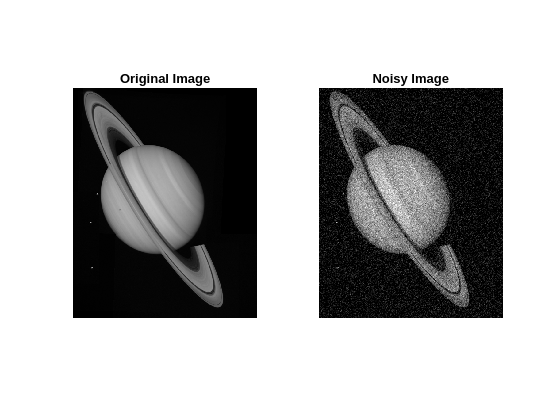

% Load "saturn.png"
saturn = imread('saturn.png');

% 6.1 and 6.2 Convert to grayscale and double, then add Gaussian noise
gray_saturn = rgb2gray(saturn);
double_saturn = im2double(gray_saturn);
noise_mean = 0;
noise_var = 0.01;
noisy_saturn = double_saturn + sqrt(noise_var) * randn(size(double_saturn)) + noise_mean;


% View the original and noisy image
figure;

% Original Image
subplot(1, 2, 1);
imshow(gray_saturn);
title('Original Image');

% Noisy Image

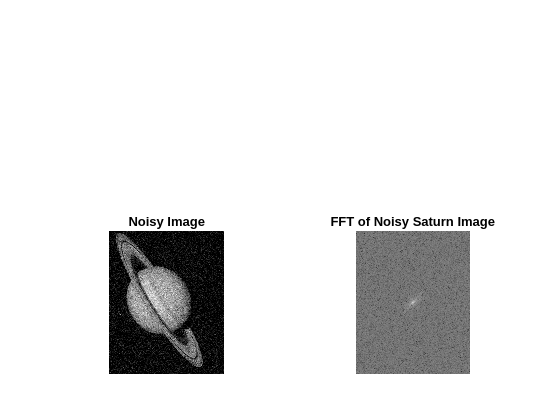

subplot(1, 2, 2);
imshow(noisy_saturn);
title('Noisy Image');
% 6.2 (Optional) Obtain and display the FFT
fft_saturn = fftshift(fft2(noisy_saturn));

% Display the magnitude of the FFT
figure;

% Original Image
subplot(2, 2, 3);
imshow(noisy_saturn);
title('Noisy Image');


subplot(2, 2, 4);
imshow(log(abs(fft_saturn)), []);
title('FFT of Noisy Saturn Image');

% 6.3 Apply different filters in the space and frequency domain
% A Wiener filter in the space domain
wiener_filter = deconvwnr(noisy_saturn, fspecial('gaussian', [5 5], 2), noise_var);

% A low-pass filter in the space domain
mask_size = 11; % Adjust the filter size as needed
low_pass_filter = fspecial('gaussian', [mask_size mask_size], 2);
filtered_space_domain = imfilter(noisy_saturn, low_pass_filter, 'replicate');

% An ideal low-pass filter in the frequency domain (optional)
radius = 50; % Adjust the radius as needed
filtered_freq_domain = ideal_low_pass_filter(noisy_saturn, radius);

% A Gaussian filter in the space domain
sigma = 2; % Adjust the sigma value as needed
filtered_gaussian = imgaussfilt(noisy_saturn, sigma);


% Create a figure to display the images
figure;

% Noisy Image
subplot(2, 3, 1);
imshow(noisy_saturn);
title('Noisy Image');

% Wiener Filter (Space Domain)
subplot(2, 3, 2);
imshow(wiener_filter);
title('Wiener Filter (Space Domain)');

% Low-Pass Filter (Space Domain)
subplot(2, 3, 3);
imshow(filtered_space_domain);
title('Low-Pass Filter (Space Domain)');


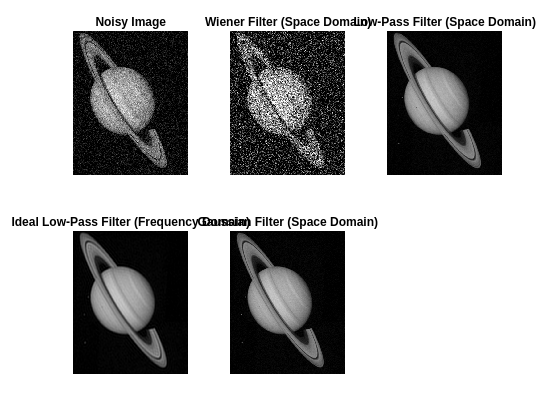

% Ideal Low-Pass Filter (Frequency Domain)
subplot(2, 3, 4);
imshow(filtered_freq_domain);
title('Ideal Low-Pass Filter (Frequency Domain)');

% Gaussian Filter (Space Domain)

subplot(2, 3, 5);
imshow(filtered_gaussian);
title('Gaussian Filter (Space Domain)');



function filtered_image = ideal_low_pass_filter(input_image, radius)
    fft_image = fftshift(fft2(input_image));
    [rows, cols] = size(fft_image);
    center = [rows / 2, cols / 2];

    % Create a mask for the ideal low-pass filter
    mask = zeros(size(fft_image));
    for i = 1:rows
        for j = 1:cols
            if sqrt((i - center(1))^2 + (j - center(2))^2) <= radius
                mask(i, j) = 1;
            end
        end
    end

    % Apply the filter in the frequency domain
    filtered_image = ifft2(ifftshift(fft_image .* mask));
end
